# **EE Lab 1**

# Factor Analysis for achieving high efficiency Solar PV Cells

## **[1] ****Introduction**

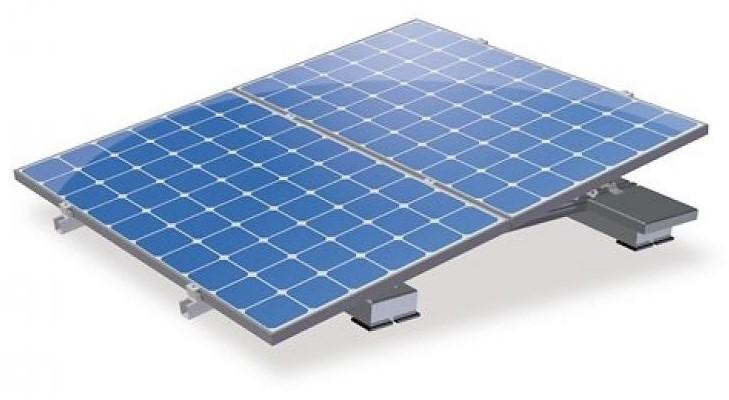

### **1.1** **Why we need higher efficiencies?**

Power = 15*10^12;
disp(strcat("Current Global Energy need = ",num2str(15)," TW"));

Current Global Energy need = 15 TW


Efficiency =68;
Irradiance =211;
Area_Needed = strcat(num2str(round(Area(Power,Efficiency,Irradiance)))," km^2");
disp(strcat("Area needed to be covered using Solar Cells = ",Area_Needed));

Area needed to be covered using Solar Cells = 104544 km^2


Equation used,

$A=\frac{P}{\eta *\sigma }$ where     $\begin{array}{l}
A-\textrm{Area}\;\textrm{needed}\\
P-\;\textrm{Current}\;\textrm{global}\;\textrm{energy}\;\textrm{need}\\
\eta -\;\;\textrm{Efficiency}\;\textrm{of}\;\textrm{the}\;\textrm{solar}\;\textrm{cell}\\
\sigma -\;\textrm{Irradiance}
\end{array}$

If we assumed 10% efficiency which is well within reach of current technology, area of 150,000 ${\textrm{km}}^2$ needed to be covered using Solar Cells to provide for the world's current energy need.

To calculate a more realistic area on Earth needed to cover our energy consumption we need to add some assumptions to consider the day/night cycle, as well as atmospheric conditions. 

Average_DayLight_Hours =13;
Percentage_Sunshine =35;
%more practical calculation of Area needed to cover up using solar cells%
Area_Needed = strcat(num2str(round(RealisticArea(Power,Efficiency,Irradiance,Average_DayLight_Hours,Percentage_Sunshine)))," km^2");
disp(strcat("Area needed to be covered using Solar Cells = ",Area_Needed));

Area needed to be covered using Solar Cells = 551442 km^2


If we assume eight hours of average daylight and that 70% of all days have sunshine, we can calculate a realistic area needed to supply the world with solar power is around 640000 ${\textrm{km}}^2$.

This is a large area, in fact it is **roughly size of France**.

If we place all the solar panels in the Sahara desert in Africa with its area of 9,200,000 square kilometers, we can find space for our world energy producing solar park **14 times**. Realistically we would need to distribute the solar panels all over the world to produce power matching demand. We will also need to find solutions to store energy when the sun is not shining.

### **1.2 ****Theoretical Efficiency of a Solar Cell**

When we create solar cells, the efficiency is the parameter that typically gets the most attention. The higher the efficiency, the better we use the available solar resource, and the smaller an area we need. Ideally, a solar cell would use every single photon available and use all of the energy from each photon ensuring that we have a 100% efficient solar cell. However, there are limits to the efficiency we can achieve.

While we can improve solar cell efficiency, there are limits to a solar cells efficiency that we cannot overcome, and from these we can determine a **theoretical solar cell efficiency.**

#### **Spectral efficiency**

A** fundamental limit** to the efficiency of a solar cell has to do with the bandgap of the semiconductor used. Photons with energy less than the bandgap does not get absorbed and photons with energy exceeding the bandgap **lose their excess energy through thermalization**.

                                                    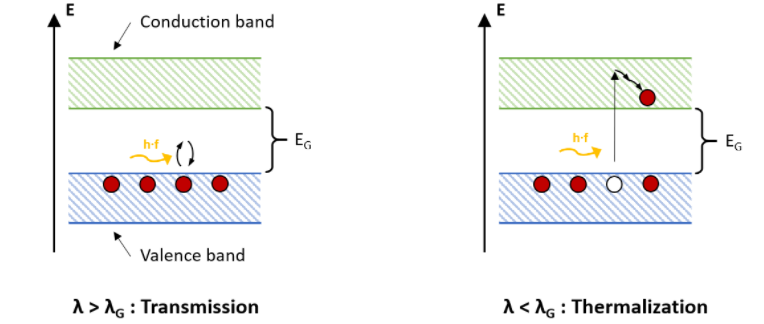

where $\lambda_G$ is the bandgap wavelength (corresponds to the wavelength of light that is just absorbed) and,

                $\lambda_G$ = $\frac{h\ldotp c}{E_G }$   

Figure in the left illastrates the process when a photon has a lower energy than the band gap of the solar cell material and the figure in the right illastrates the process when a photon has a higher energy than the band gap of the solar cell material. In both types part of the energy or the whole energy of the photon is lost. 

**Transmission:** Photon s with less energy than the bandgap ($E_G$) it will not be absorbed. 

**Thermalization:** Photons with higher energy than the bandgap lose their excess energy in a thermalization process.

Following figure illastrates a visualization of the spectral usage for a silicon solar cell with a bandgap of 1.11 eV.

                                          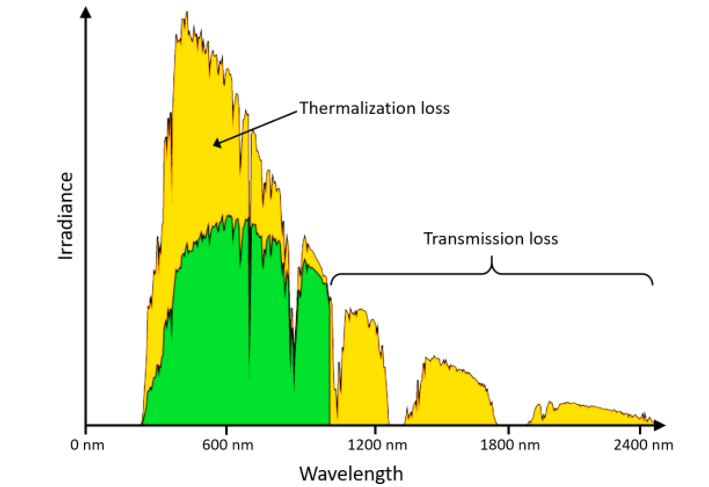

All photons with an energy lower than the bandgap are lost to transmission, while higher energy photons lose their excess energy to thermalization. Spectral efficency comes with the material used for the solar cell. Therefore, while using the same mateial we cannot overcome this limitation for the efficiency.

                                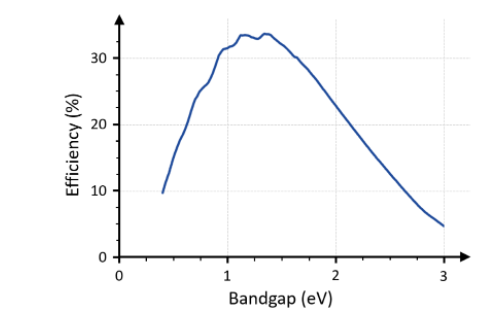

Above figure illastrates a visualization of Theoretical efficiency and its dependence on the bandgap energy. The wiggles in the curve are a result of the IR absorption bands in the atmosphere

For Silicon solar cells theoretical efficiency is 32.33$%$.

## **[2] ****Modeling a Solar Cell**

Here you can see a basic mathematical model for the output current of a solar cell.

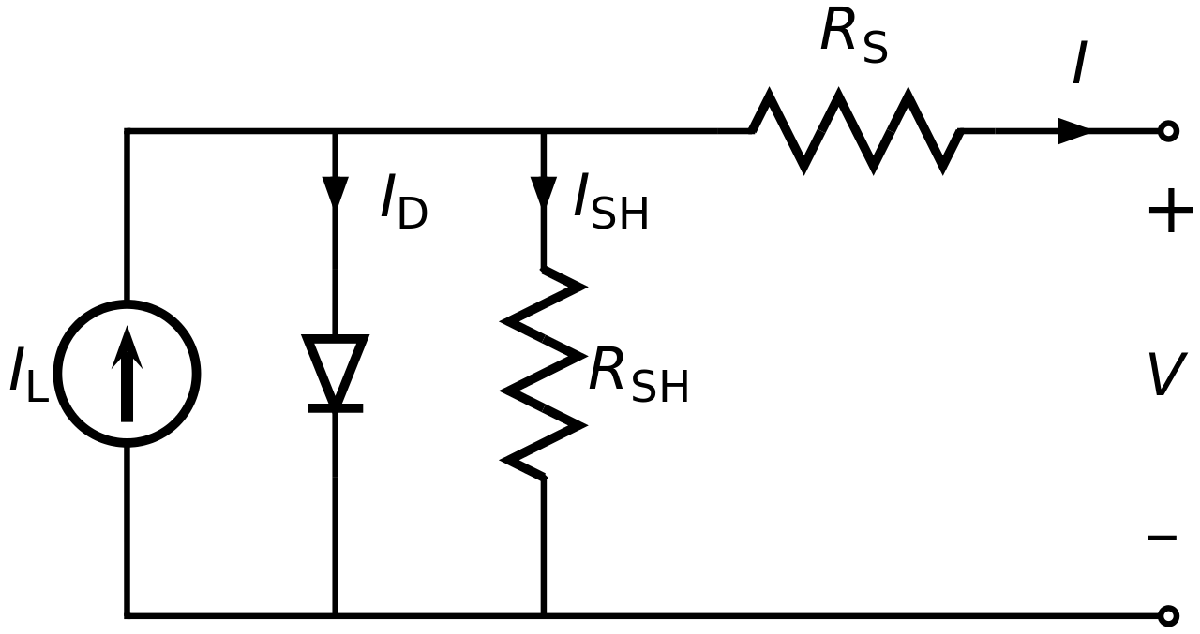             where,

                                                                                                $q$ is the charge on the electron

                                                                                                $n$ is the quality factor

                                                                                                $k$ is the Boltzmann's constant

                                                                                                $T$ the cell temperature in Kelvin

                                                                                                $I$ is the solar-generated current

Since our goal is to examine the factors affecting solar cell efficiency in real world applications, we will not use this basic model in simulation models that you will see as you go through the lab. Instead we will use the following model,

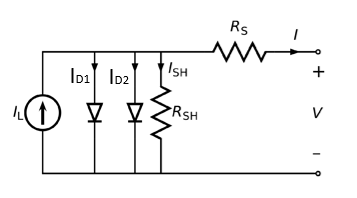

                                $I=I_L -I_{\textrm{S1}} \left\lbrace \exp \left\lbrack \frac{\left(V+I*R_S \right)}{N_1 *V_T }\right\rbrack -1\right\rbrace -I_{\textrm{S2}} \left\lbrace \exp \left\lbrack \frac{\left(V+I*R_S \right)}{N_2 *V_T }\right\rbrack -1\right\rbrace -\frac{\left(V+I*R_S \right)}{R_{\textrm{SH}} }$ ; 

where, 

                  
$$I_{\textrm{D1}} =\;$$

$$I_{\textrm{S1}} \left\lbrace \exp \left\lbrack \frac{\left(V+I*R_S \right)}{N_1 *V_T }\right\rbrack -1\right\rbrace$$


                  
$$I_{\textrm{D2}} =\;$$

$$I_{\textrm{S2}} \left\lbrace \exp \left\lbrack \frac{\left(V+I*R_S \right)}{N_2 *V_T }\right\rbrack -1\right\rbrace$$


                  
$$I_{\textrm{SH}} =\;\frac{\left(V+I*R_S \right)}{R_{\textrm{SH}} }$$


                   $V_T =\frac{k*T}{q}$ is the Thermal Voltage

This block models a solar cell as a parallel combination of a current source($I_L$), two exponential diodes and a parallel resistor($R_{\textrm{SH}}$ / $R_P$), that are connected in series with a resistance($R_S$). $I_{\textrm{S1}}$ and $I_{\textrm{S2}}$ are the diode saturation currents, $N_1$ and $N_2$ are the quality factors.

The solar cell power conversion efficiency can be given as:


$$\eta_c =\frac{P_{\max } }{P_{\textrm{in}} }=\frac{I_{\max } *V_{\max } }{I\left(t\right)*A_c }$$


Where $I_{\max }$and $\;V_{\max }$ are the **current and voltage for maximum power**, corresponding to solar intensity ($I\left(t\right)$) and $A_c$ is Area of solar cell

## [3] Factors affecting Solar Cell Efficiency

Here we discuss some of the important factors that affects solar cell efficiency. Since when calculating efficiency of a solar cell, we consider the total power recieved to the cell as a constant, we can simply consider the power output of the cell as the efficiency($I_{\max } *V_{\max }$).

### 1: Reflection/Absorption effect on Power Output of a Solar Cell

When we talk about **optimizing the efficiency of solar cells**, one extremely important aspect is how much light gets absorbed by the solar cell. We will talk about two aspects affecting the amount of light absorbed in the solar cell. One part of this is the **reflection losses** when the light hits the surface of the solar cell. The other is the **absorption **by the material itself.

### **Reflection losses**

When light hits a solar cell, it has to pass from one material (air) to another (silicon). Each of these two materials have a different **refractive index** (n) meaning that light travels at different speeds in either material. This change in material properties results in reflection from the surface of the second material and the larger the difference in refractive index from one material to another, the larger the reflection loss. We can write the strength of the reflection given by the reflection factor R


$$R=\frac{E_R }{E_0 }$$


Where $E_0$ is the **incident irradiance** and $E_R$ is the **reflected irradiance**. For incoming light perpendicular to the surface, the reflection factor is calculated as


$$R={\left(\frac{n_1 -n_2 }{n_1 +n_2 }\right)}^2$$
 

In the case of **Silicon** the index of refraction in the visible spectrum is around** 3.9** while air has a refractive index of 1, so we get 

$R={\left(\frac{n_1 -n_2 }{n_1 +n_2 }\right)}^2$= ${\left(\frac{3\ldotp 9-1}{3\ldotp 9+1}\right)}^2$= 35.03$%$

This means that we stand to **lose approximately one third of the light**. If we consider the case of oblique incidence of radiation the reflection losses only increases. It is therefore clear that we need to **reduce the reflective loss** if we want to make an efficient solar cell, and for this reason, we apply **anti-reflective coatings**. The simplest way to create an anti-reflective coating is to introduce a material in-between air and silicon with an in-between index of refraction. There are also other strategies including** textured surfaces (nanotexturing)** etc. We will not go much deeper with the topic of anti-reflective coatings, but it is important to notice that solar cells using **semiconductors with large indexes of refraction require anti-reflective coatings** in order to be efficient.

                                                                                                                          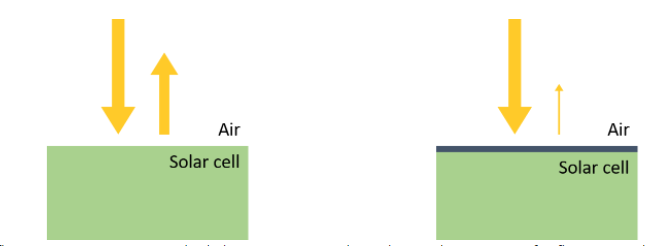

Following Model illastrates how Reflection affects efficiency of a solar cell. 

**Simulink Model**

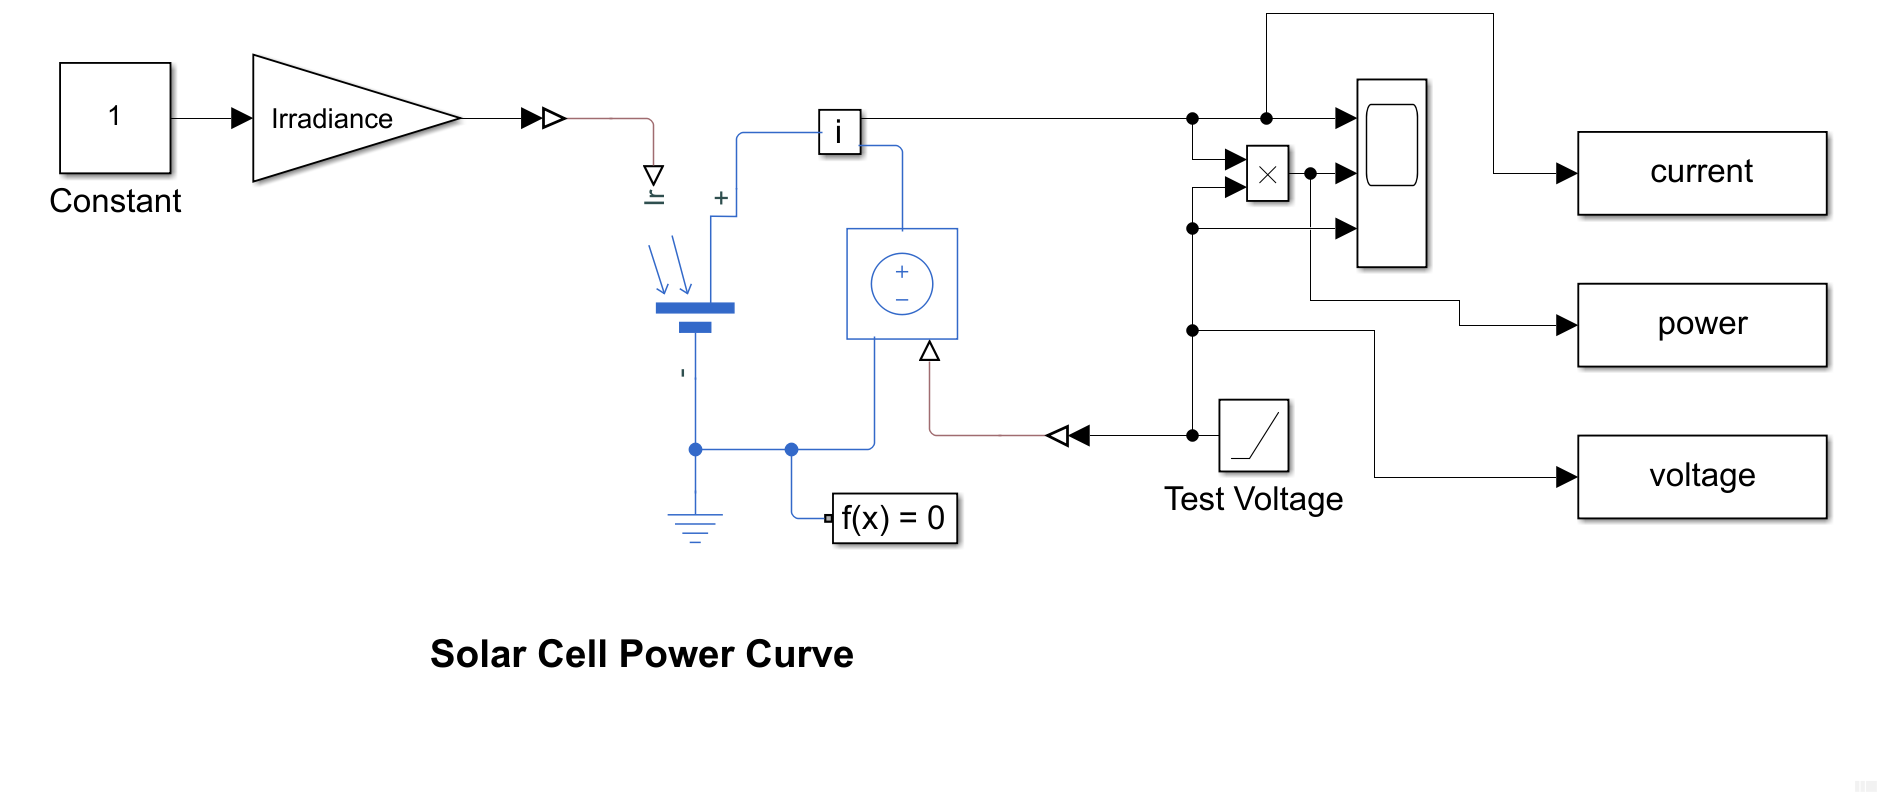

Click to open the Model,

 
open_system('ee_solar_cell.slx');

Here you can see how Power Output of a solar cell changes with the percentage reflection of light,

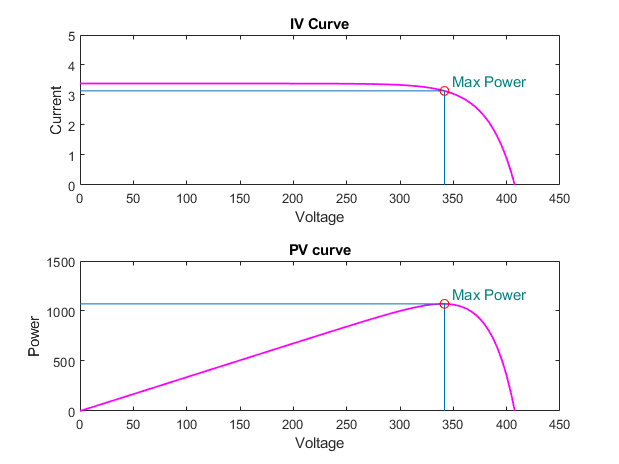

 Reflection =11;
 % To eliminate the dependency from next section
 Irradiance = 10*(100 - Reflection);
 temperature = 25;
 series_resistance = 0;
 parallel_resistance = inf;

 load_system('ee_solar_cell.slx');
 sim('ee_solar_cell.slx');
 tiledlayout('flow');
 
 % plot
 plotCurves(voltage, current, power, 450, 5, 1500);

### Absorption Loss 

We previously assumed that all photons which are not reflected are absorbed by the cell if it has enough energy cause an electron to transition from the valance band to the conduction band, we made a significant simplification. In our depiction of the valance band and conduction band, we forgot the **crystal momentum**. For some semiconductors, our simplification has no consequences if they are **direct bandgap materials**, see figure below.

Some materials have an** in-direct bandgap** and in those cases, an **electron cannot shift from the highest energy state in the valence band to the lowest energy state in the conduction band without a change in momentum**. A crystal vibration causes this change in momentum and the important consequence is that absorption is far less likely. A photon with energy close to the band gap can penetrate **much deeper** into the semiconductor before being absorbed in an in-direct band gap material as compared to a direct band gap one. This fact is very important for solar cells, as **silicon is an indirect-gap material** and therefore does not absorb light very well. Silicon solar cells are typically hundreds of microns thick and if they were much thinner, light (particularly infrared) would simply pass through.

                                                                    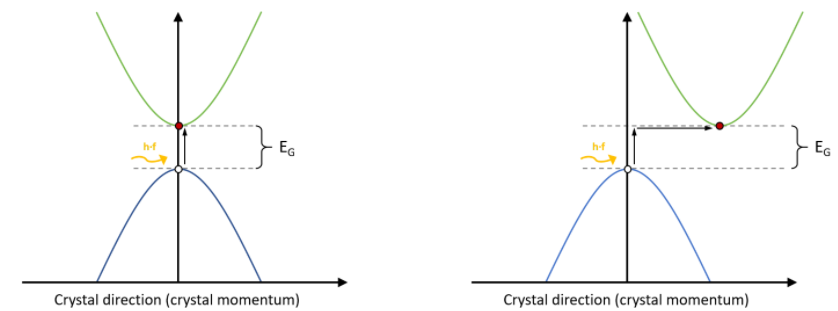

### 2: Temperature effect on Power Output of a Solar Cell


$$I=I_L -I_{\mathrm{S1}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_1 *V_T }\right\rbrack -1\right\rbrace -I_{\mathrm{S2}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_2 *V_T }\right\rbrack -1\right\rbrace -\frac{\left(V+I*R_S \right)}{R_{\mathrm{SH}} }$$


As temperature increases, the band gap of the silicon shrinks, and the open circuit voltage ($V_{\mathrm{OC}}$ ) decreases following the p-n junction voltage temperature dependency of seen in the diode factor q kT. Solar cells therefore have a **negative temperature coefficient of **$V_{\mathrm{OC}}$. Moreover, a lower output power results given the same photocurrent because the charge carriers are liberated at a lower potential. Using the convention introduced  with the Fill Factor calculation, a reduction in VOC results in a smaller theoretical maximum power $P_{\mathrm{MAX}} =I_{\mathrm{SC}} *V_{\mathrm{OC}}$ given the same short-circuit current $I_{\mathrm{SC}}$. As temperature increases, again the band gap of the silicon shrinks meaning more incident energy is absorbed because a greater percentage of the incident light has enough energy to raise charge carriers from the valence band to the conduction band. A larger photocurrent results; therefore, $I_{\mathrm{SC}}$ increases for a given insolation, and solar cells have a **positive temperature coefficient of **$I_{\mathrm{SC}}$. 

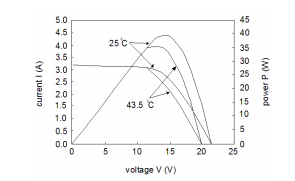

Above figure shows the I-V and P-V characteristics at the constant irradiance when the temperature changes. Temperature effects are the result of an inherent characteristic of crystalline silicon cell-based modules. They tend to produce higher voltage as the temperature drops and, conversely, to lose voltage in high temperatures. Any solar panel or system derating calculation must include adjustment for this temperature effect.

We use the same model we used before to demonstrate how temperature affects the Power Output of a solar cell. `

Click to open the Model,

 
open_system('ee_solar_cell.slx');

Here you can see how Power Output of a solar cell changes with Temperature,

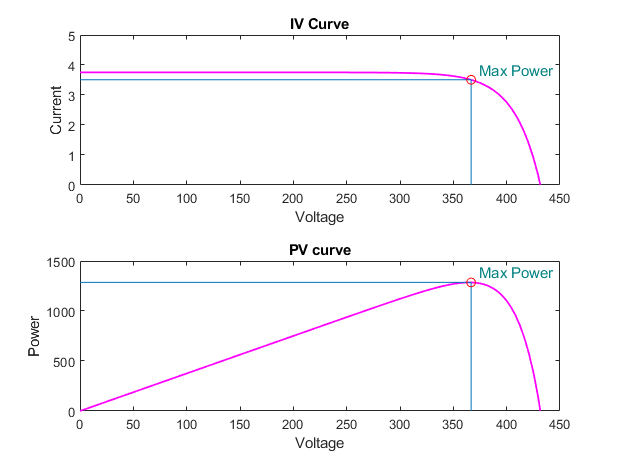

 temperature =10;
 
 Irradiance = 1000;
 series_resistance = 0;
 parallel_resistance = inf;

 load_system('ee_solar_cell.slx');
 sim('ee_solar_cell.slx');
 tiledlayout(2,1);
 
 % plot
 plotCurves(voltage, current, power, 450, 5, 1500);

### 3: Effect of Series Resistance($R_S$) on Power Output of a Solar Cell


$$I=I_L -I_{\mathrm{S1}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_1 *V_T }\right\rbrack -1\right\rbrace -I_{\mathrm{S2}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_2 *V_T }\right\rbrack -1\right\rbrace -\frac{\left(V+I*R_S \right)}{R_{\mathrm{SH}} }$$


Effect of Series Resistance is not simply a matter of any series resister. Voltage reduction due to series resistance has a direct impact on output cell current.

We use the same model we used before to demonstrate how Series Resistance($R_S$) affects the Power Output of a solar cell. 

Click to open the Model,

 
open_system('ee_solar_cell.slx');

Here you can see how Power Output of a solar cell changes with Temperature,

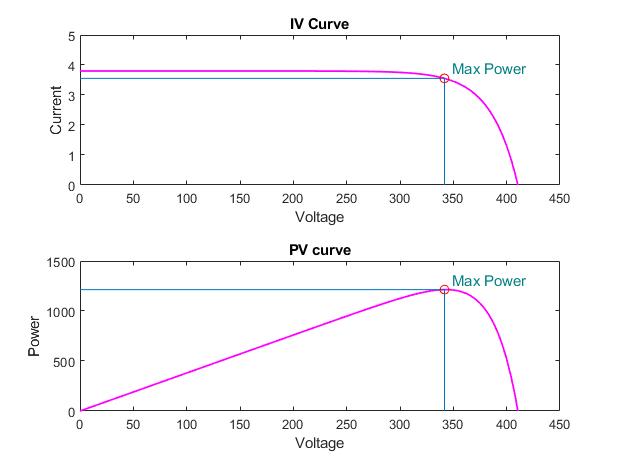

 series_resistance =0;
 
 Irradiance = 1000;
 temperature = 25;
 parallel_resistance = inf;

 load_system('ee_solar_cell.slx');
 sim('ee_solar_cell.slx');
 tiledlayout(2,1);
 
 % plot
 plotCurves(voltage, current, power, 450, 5, 1500);

### 4**: **Effect of Parallel Resistance($R_{\textrm{SH}}$)** on Power Output of a Solar Cell**


$$I=I_L -I_{\mathrm{S1}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_1 *V_T }\right\rbrack -1\right\rbrace -I_{\mathrm{S2}} \left\lbrace \mathrm{exp}\left\lbrack \frac{\left(V+I*R_S \right)}{N_2 *V_T }\right\rbrack -1\right\rbrace -\frac{\left(V+I*R_S \right)}{R_{\mathrm{SH}} }$$


The shunt resistance represents any parallel high conductivity paths (shunts) across the solar cell p-n junction or on the cell-edges. These are due to the crystal scratch and impurities in and near the junction, and give rise to the shunt current. Shunt paths lead the current away from the intentional load, and their effects are harmful to the module performance mainly at low intensity levels.

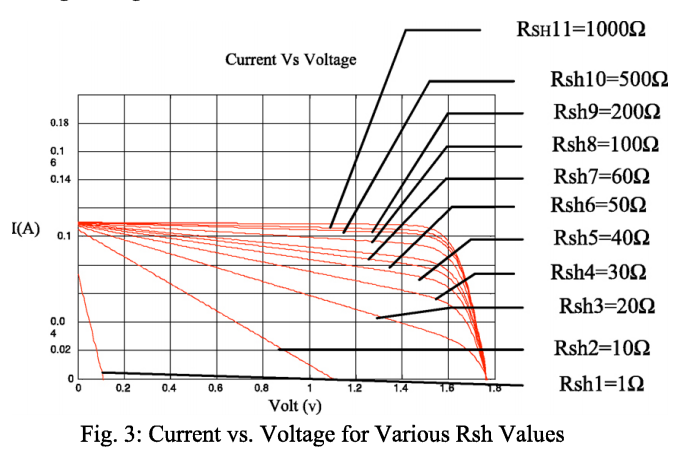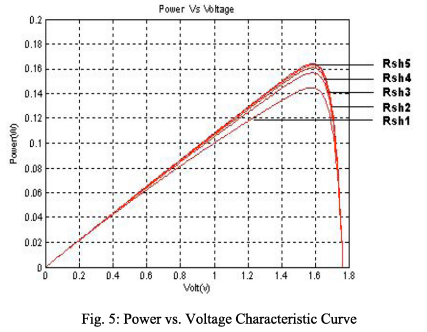

Above figures show the current-voltage characteristics of a typical solar cell for various values of shunt resistance (Rs is constant). The characteristic curve is drawn by using MATLAB program. The various ranges of shunt resistances are In, ion, 20n, 30n, 40n, 50n, 60n, loon, 200n, 500n, and 1000n. Decreasing the shunt resistance has an overall impact in reducing the voltage value. Similarly, an increasing the shunt resistance, the voltage of the photovoltaic cell also increases rapidly. At this point, the output power also changes its value based on the changes of the voltage and current of the typical photovoltaic cell.

We use the same model we used before to demonstrate how Parallel Resistance affects the Power Output of a solar cell. 

Click to open the Model,

 
open_system('ee_solar_cell.slx');

Here you can see how Power Output of a solar cell changes with Parallel Resistance,

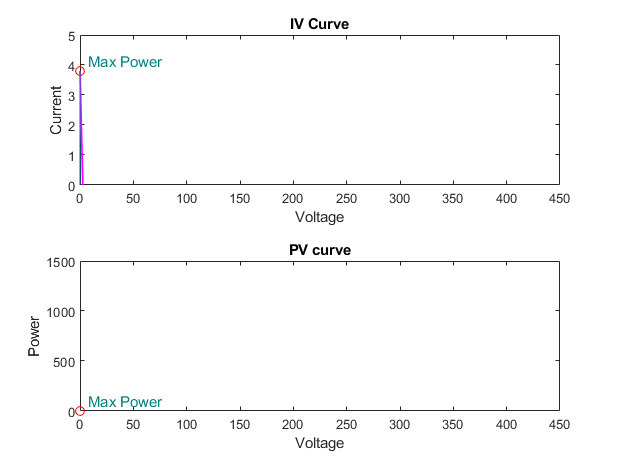

 parallel_resistance =0.001;
 
 Irradiance = 1000;
 temperature = 25;
 series_resistance = 0;

 series_resistance = 0;
 load_system('ee_solar_cell.slx');
 sim('ee_solar_cell.slx');
 tiledlayout(2,1);
 
 % plot
 plotCurves(voltage, current, power, 450, 5, 1500);

### 5: **Shadow Effects on Power Output of a Solar Cell**

It is important to consider what happens when one or more solar cells in such connections are in **shadow**. 

In figure 1 you can see how a shaded cell in a module affects the overall module performance. To draw this plot it is assumed that the shaded cell is 90% shaded. From earlier we know that the **open circuit voltage of a shaded cell only changes slightly**, while the **short circuit current will drop** with around 90%. The overall IV curve for a module decays with roughly the amount of current loss from the one shaded cell. Thus the overall power loss of the module corresponds to the shaded area. This means that a parallel connection is nicely behaved in partial shading losing only the shaded area. 

                                                                                                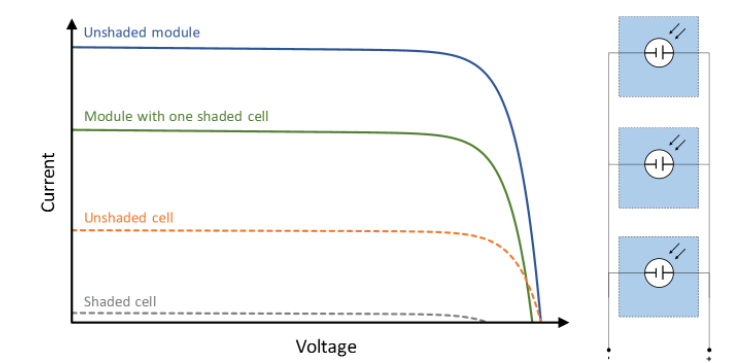

While the parallel connection is relatively good-natured when it comes to partial shading, the same cannot be said for a series connection, as can be seen from figure 2. With one shaded cell in the series connection the two other cells must push their current through the shaded cell. This causes a negative voltage over the shaded cell. The current is limited by the shaded cell and therefore the overall current of the module is limited. As can be seen from figure two, this effect reduces the power output from the module with a single shaded cell significantly.

                                                                                         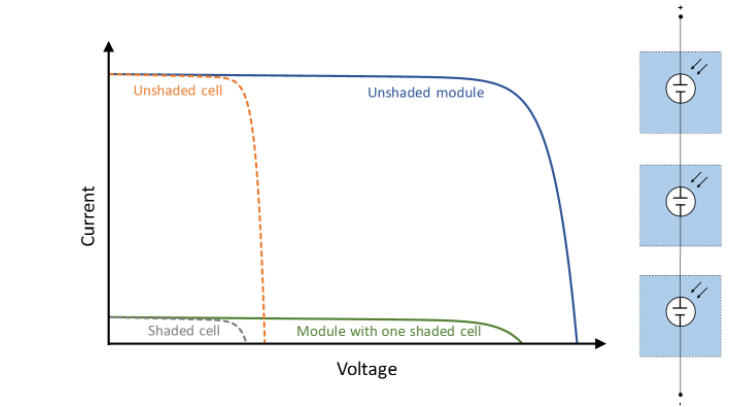

A solution to the problem with series connection is to employ a **bypass diode over the shaded cell**, see figure 3. Bypass diodes allow current to pass shaded cells and thereby reduce the voltage losses through the module. When a module becomes shaded its bypass diode begins to conduct current through itself. With the bypass diode the current is no longer limited by the shaded cell, and the impact on the overall IV curve is greatly reduced, see figure 4.

                                                                                       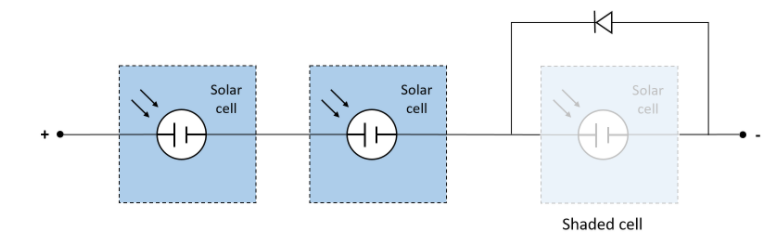

Bypass diodes also serve another purpose, namely the prevention of hotspots. In modules with one shaded cell and no bypass diode, there will be a massive heating of the shaded cell caused by the other cells. The usage of bypass diodes alleviates this problem.

In real solar modules bypass diodes are not employed for each cell. The reason is that the diodes would have to be incorporated into the encapsulation if the solution should be practical. Instead bypass diodes are employed for strings of cells (e.g. 12, 18, or 24 cells). It is therefore important that modules are not mounted in places were partial shading is expected during the day.

Click to open the Model,

 
 open_system('SolarCellModel2.slx');

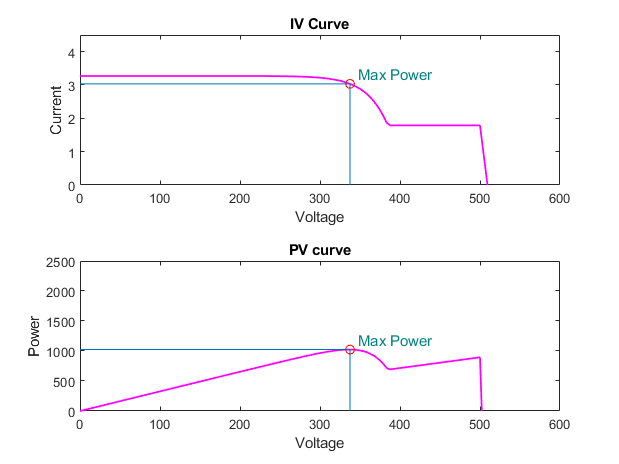

Irradiance11 =471;
Irradiance21 =381;
Irradiance31 =271;
Irradiance41 =861;

 temperature = 25;
 series_resistance = 0;
 parallel_resistance = inf;

 load_system('SolarCellModel2.slx');
 sim('SolarCellModel2.slx');
 tiledlayout(2,1);
 
 % plot
 plotCurves(voltage, current, power, 600, 4.5, 2500);

## [4] References

[1]: [https://www.researchgate.net/publication/239441364_Critical_Factors_that_Affecting_Efficiency_of_Solar_Cells](https://www.researchgate.net/publication/239441364_Critical_Factors_that_Affecting_Efficiency_of_Solar_Cells)

  Furkan Dinçer, Mehmet EminMeral University of Yuzuncu Yil, Department of Electrical and Electronics Engineering, Van, Turkey. Received February 17th, 2010; revised May 7th, 2010; accepted May 8th; Critical Factors that Affecting Efficiency of Solar Cells. January 2010

Smart Grid and Renewable Energy 01(01):47-50. DOI: [10.4236/sgre.2010.11007](https://www.researchgate.net/deref/http%3A%2F%2Fdx.doi.org%2F10.4236%2Fsgre.2010.11007) 

[2]: [https://sci-hub.do/10.1109/ICETEEEM.2012.6494522](https://sci-hub.do/10.1109/ICETEEEM.2012.6494522) 

  Dhass, A. D., Natarajan, E., & Ponnusamy, L. (2012). Influence of shunt resistance on the performance of solar photovoltaic cell. 2012   International Conference on Emerging Trends in Electrical Engineering and Energy Management (ICETEEEM).      DOI:10.1109/iceteeem.2012.6494522 

[3]: [https://sci-hub.do/https://www.tandfonline.com/doi/abs/10.1080/01430750.2016.1181567](https://sci-hub.do/https:/www.tandfonline.com/doi/abs/10.1080/01430750.2016.1181567)

  Abdulrahman Babiker Hussain, Abdelrahman S. Abdalla, Abdellahi Sidi Mukhtar, M. Elamin, R. Alammari & A. Iqbal (2016):      Modeling and Simulation of Single and Triple Junction Solar Cell Using MATLAB/SIMULINK, International Journal of Ambient   Energy, DOI:  10.1080/01430750.2016.1181567 

[4]: [https://sci-hub.do/https://www.sciencedirect.com/science/article/pii/S2352484717302378](https://sci-hub.do/https:/www.sciencedirect.com/science/article/pii/S2352484717302378) 

  Pendem, S. R., & Mikkili, S. (2018). Modeling, simulation and performance analysis of solar PV array configurations (Series, Series–  Parallel and Honey-Comb) to extract maximum power under Partial Shading Conditions. Energy Reports, 4, 274287.   DOI:10.1016/j.egyr.2018.03.003 

[5]: [https://sci-hub.do/https://www.academia.edu/download/33409367/157-868-2-PB.pdf](https://sci-hub.do/https:/www.academia.edu/download/33409367/157-868-2-PB.pdf) 

  Tarak Salmi, Mounir Bouzguenda, Adel Gastli, Ahmed Masmoudi(2012): MATLAB/Simulink Based Modelling of Solar Photovoltaic Cell,   International Journal of Renewable Energy Research,Vol.2, No.2, 2012

[6]: [https://www.coursera.org/learn/solar-cells](https://www.coursera.org/learn/solar-cells)

%functionsNeeded 

function A = Area(P,n,Irr)
    A = (P)/(0.01*n*Irr*10^6);
end

function A = RealisticArea(P,n,Irr,a,b)
    A = (P)/(0.01*n*Irr*10^6);
    A = A*(100/b)*(24/a);
end

function plotCurves(voltage, current, power, x_lim, y1_lim, y2_lim)

     [M,I] = max(power);
     x = voltage(I);
     y1 = power(I);
     y2 = current(I);
     % Top plot
     ax1 = nexttile;
     plot(voltage,current,"Color",[1 0 1],"LineWidth",1.2);
     hold on
     line([0,x],[y2,y2]);
     line([x,x],[0,y2]);
     plot(x,y2,'or');
     text(x,y2,'  Max Power',"Color",[0,0.5,0.5],"HorizontalAlignment","left","VerticalAlignment","bottom");
     title(ax1,'IV Curve');
     ylabel(ax1,'Current');
     xlabel(ax1, 'Voltage')
     ylim([0 y1_lim]);
     xlim([0 x_lim]);
     
     % Bottom plot
     ax3 = nexttile;
     plot(voltage,power,"Color",[1 0 1],"LineWidth",1.2);
     hold on
     title(ax3,'PV curve');
     ylabel(ax3,'Power');
     xlabel(ax3, 'Voltage');
     ylim([0 y2_lim]);
     xlim([0 x_lim]);
     line([0,x],[y1,y1]);
     line([x,x],[0,y1]);
     plot(x,y1,'or');
     text(x,y1,'  Max Power',"Color",[0,0.5,0.5],"HorizontalAlignment","left","VerticalAlignment","bottom");
     
end
